# **Explore 2-DOF Spring Mass Damper   - STEP responses        **

In this example we're going to study the two degree of freedom (dof)  mechanical system shown below:

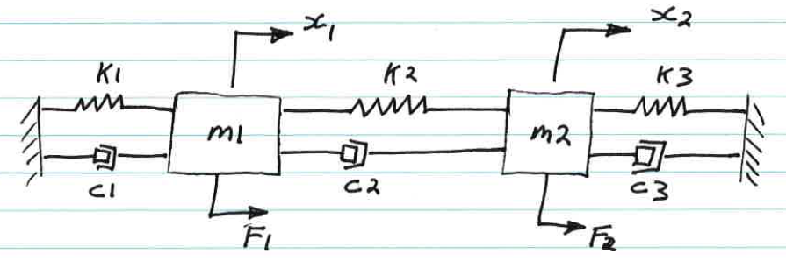 

In this tutorial we're going to look at the following subtopics:

$\qquad \bullet
$ apply Newton's laws to derive the system's dynamic equation of motion

$\qquad \bullet
$ automatically convert our system of ODEs into a Simulink block

`Bradley Horton : 01-Mar-2016, bradley.horton@mathworks.com.au`

**Apply Newton's law:**

The free body diagram for this system is shown below:

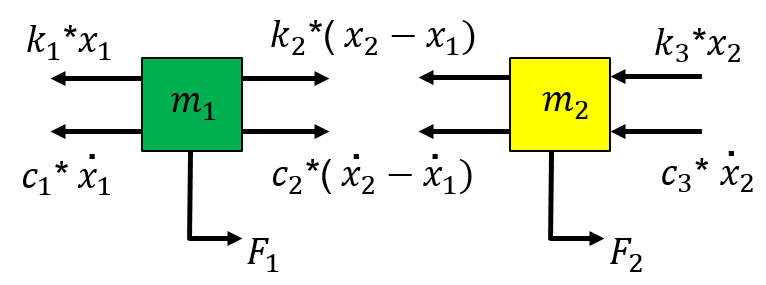

For the 1st mass we have:


$$m_1 \thinspace \ddot{x_1} = F_1 + k_2(x_2 - x_1) + c_2(\dot{x_2} - \dot{x_1}) - k_1x_1 - c_1 \dot{x_1}$$
 


$$m_1 \thinspace \ddot{x_1} = F_1  +  x_1(-k_2 + -k_1) +   x_2(k_2) +  \dot{x_1}(-c_2 + -c_1) +   \dot{x_2} (c_2) 
$$
 

For the 2nd mass we have:


$$m_2 \thinspace \ddot{x_2} = F_2 - k_2(x_2 - x_1) - c_2(\dot{x_2} - \dot{x_1}) - k_3x_2 - c_3 \dot{x_2}$$


 
$$m_2 \thinspace \ddot{x_2} = F_2  +  x_1(k_2) + x_2(-k_2 + -k_3) + \dot{x_1}(c_2) + \dot{x_2}(-c_2 + -c_3)$$


We can combine the two 2nd order ODEs into a matrix equation, ie:

$\pmatrix{
m_1 & 0 \cr
0 & m_2 \cr
}$$\times \pmatrix{
\ddot{x}_1 \cr
\ddot{x}_2 \cr
}$ + $\pmatrix{
(c_1 + c_2) & -c_2 \cr
-c_2 & (c_2+c_3) \cr
}$$\times \pmatrix{
\dot{x}_1 \cr
\dot{x}_2 \cr
}$ + $\pmatrix{
(k_1 + k_2) & -k_2 \cr
-k_2 & (k_2+k_3) \cr
}$$\times \pmatrix{
{x}_1 \cr
{x}_2 \cr
}$= $\pmatrix{
{F}_1 \cr
{F}_2 \cr
}$

which we can refer to as:   $M \ddot{X} + C\dot{X} + KX = F$where $X  = 
\pmatrix{ x_1 \cr
               x_2}

\in R^{n\times1}$

**Define the Mechanical system parameters:**

Note all parameters are in SI units, ie: *kg, N/m, N/(m/sec)*

syms m1 m2 
syms k1 k2 
syms c1 c2 
syms k3 c3


**Define our dof symbols and their velocities and accelerations:**

syms x1   x1_D   x1_DD
syms x2   x2_D   x2_DD

**Define our system Excitation functions:**

syms t F1 F2

## Define our system of ODEs:

Recall our matrix representation of our overall mechanical system:

-      $M \ddot{X} + C\dot{X} + KX = F$  where $X  = 
\pmatrix{ x_1 \cr
               x_2}

\in R^{n\times1}$

So let's define the co-efficent matrices

M_mat  = [m1, 0;
          0, m2];

K_mat  = [(k1+k2), -k2;
           -k2,    (k2+k3) ];

C_mat  = [(c1+c2), -c2;
           -c2,    (c2+c3) ];

Define some variables that represent acceleration, velocity and position:

xDD_col = [x1_DD; x2_DD];
 xD_col = [x1_D ; x2_D ];   
 x_col  = [x1   ; x2   ];   
 F_col  = [F1   ; F2   ];

Now create our system of equations:

THE_EQ = (M_mat*xDD_col + C_mat*xD_col + K_mat*x_col) == F_col;

Now solve for the accelerations:

THE_ACC = solve(THE_EQ, xDD_col)

THE_ACC = struct with fields:
    x1_DD: [1×1 sym]
    x2_DD: [1×1 sym]


So what does $\ddot{x}_1
$ look like ?

THE_ACC.x1_DD

$$ans = -\frac{c_{1}\,x_{1,D}-F_{1}+c_{2}\,x_{1,D}-c_{2}\,x_{2,D}+k_{1}\,x_{1}+k_{2}\,x_{1}-k_{2}\,x_{2}}{m_{1}}$$

## Create Simulink blocks of our $\ddot{x}_1
$ and $\ddot{x}_2
$ equations:

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

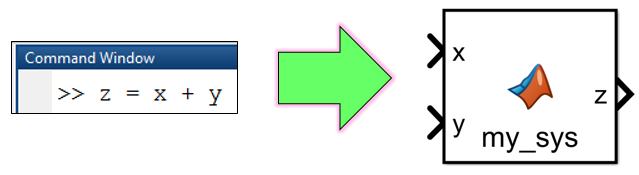

Now create the MATLAB function blocks for Simulink:

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_2dof';
    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   
                          
    % Put BOTH equations into one block 
    matlabFunctionBlock( [MODEL_NAME,'/THE_X_SYS_DD'], THE_ACC.x1_DD, THE_ACC.x2_DD, ...
                         'Optimize', false, ...
                         'Outputs', {'x1_DD', 'x2_DD'}   );     
end

The Simulink block `THE_X_SYS_DD` should look like this - NOTE also the use of $\frac{1}{s}$ integrators that integrate accelerations to get velocities and positions:

   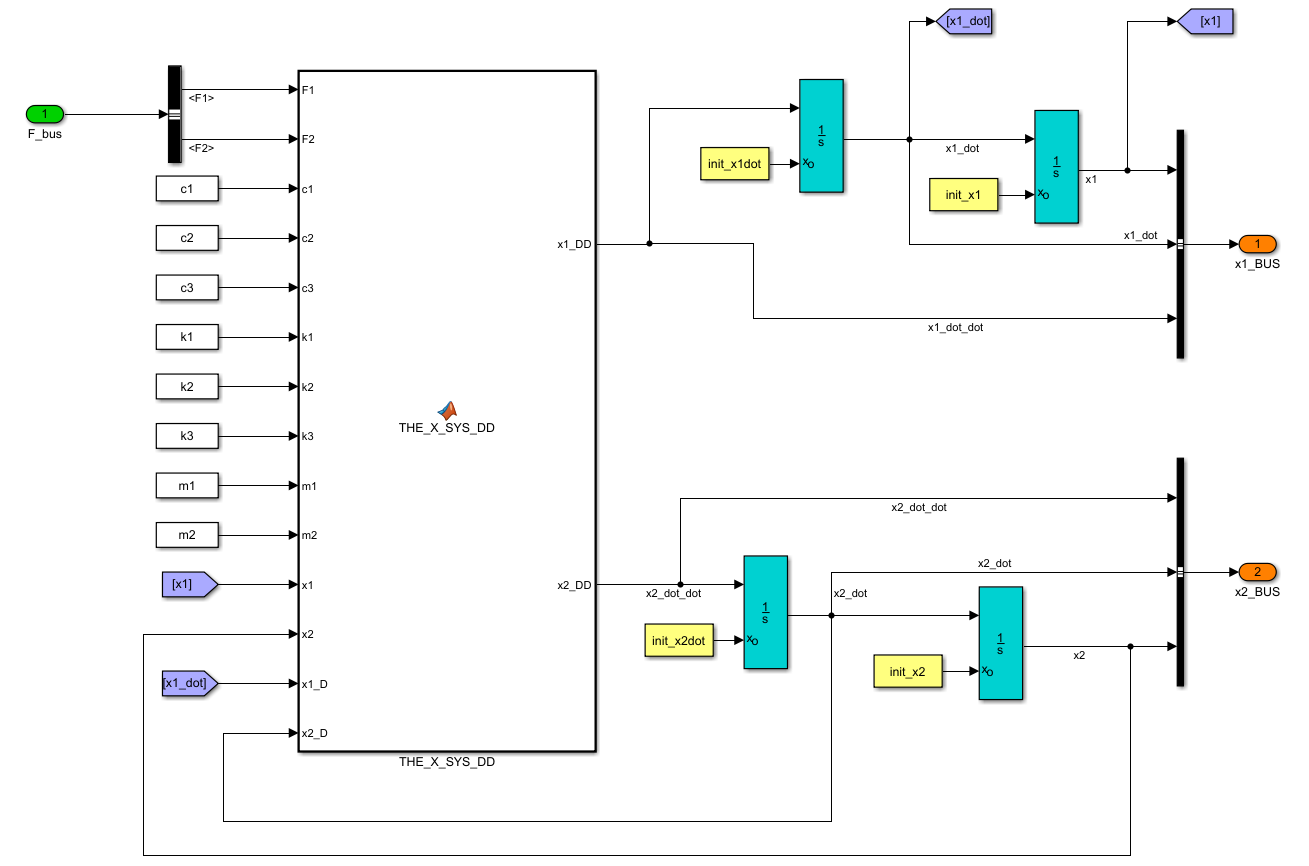

# Next steps ?

If you liked this tutorial why not have have a quick look at SIMULINK.

What is Simulink ? - good questions. Simulink is a block diagram modelling and simulation tool. So? So rather than writing lines of code, you construct mathematical models using block diagrams. A great example to look at is the Simulink model **bh_2dof_ODE_model.slx.**

And finally, why not look at an alternate way of using Simulink to model dynamic systems - it's called Simscape.  In Simscape you're still using the Simulink modelling environment, but rather than your focus being the implmentation of mathematical equations, your focus is instead on assembling a model that "physically" represents your system, eg: instead of using integrator blocks to implement ODEs in simscape you would use a spring block, a damper block, a mass block, etc.  Check it out in the following model **bh_2dof_simscape_model.slx** .